flux_period = 1109.6;
gate_period=51.2859;
Ej=15e9;
Ec=30e9;
epsilon=8.854e-12;
area=1e-5*1e-7;
x0=1e-7;
xzp=10e-15;
Cj=206.67e-18;
Cg=94e-18;
CR=131e-18;
VR=10;
h=6.626e-34;


charge_states=9;
number_points=11;    % number of points on each side of data point used to calculate derivatives
e=1.6e-19;
if number_points>11
    disp('error')
    return
end
% Ej=Ej*Ec;
E1=[];
dE1=[];
flux=[];
gate=[];
dE1squared=[];  
dE1cubed=[];
dE1fourth=[];
freq_shift=[];
E2=[];
a=[];
b=[];
flux_values_1=[];
gate_values_1=[];
 
a=linspace(-3*pi/2,3*pi/2,100);
b=linspace(-1,1,100);
gate_values_1=b;
flux_values_1=a;

 %%%%%  decides whether to plot eigenenergies or not %%%%%%%%%%%
    if ~exist('plot_display','var')
        plot_display=1;
    end
   
 %%%%%%%%%%%% always need an odd number of states to make it symmetric
 %%%%%%%%%%%% about 0 %%%%%%%%%%%%%%%
    if mod(charge_states,2)==0
        charge_states=charge_states+1;
    end
 %%%%%%%%% generate gate and flux values from experimental values %%%%%%%%
    delta_0=0.088;
    gate_spacing=diff(gate_values_1);
    if ~mean(gate_spacing)==gate_spacing(1)
        return
    end
    gate_spacing=gate_spacing(1);
    flux_spacing=diff(flux_values_1);
    if ~mean(flux_spacing)==flux_spacing(1)
        return
    end
    flux_spacing=flux_spacing(1);
    gate=[];
    flux=[];
    flux_spacing=flux_spacing(1);
    for i=1:length(gate_values_1)
        gate_temp=linspace(gate_values_1(i)-number_points*gate_spacing/20,gate_values_1(i)+number_points*gate_spacing/20,2*number_points+1);
        gate=[gate,gate_temp];
    end
%     gate=gate_values_1;
    for i=1:length(flux_values_1)
        flux_temp=linspace(flux_values_1(i)-number_points*flux_spacing/20,flux_values_1(i)+number_points*flux_spacing/20,2*number_points+1);
        flux=[flux,flux_temp];
    end
%%%%%%%%%%%%%%%%%%%%%%%%%%

    
%%%%%%% derivatives with respect to x %%%%%%%%%%%%%%%%%%%%%
CR=epsilon*area/x0

CR = 8.8540e-17

CR1=-epsilon*area/x0^2

CR1 = -8.8540e-10

CR2=2*epsilon*area/x0^3;
CR3=-6*epsilon*area/x0^4;
Csigma=2*Cj+Cg+CR

Csigma = 5.9588e-16


Ec=e^2*Csigma/Cj/(2*(Cj+Cg+CR));
Ec=Ec/h

Ec = 1.4311e+11

Ec1=-e^2/(2*(Cj+Cg+CR)^2)*CR1;
Ec1=Ec1/h;
Ec2=-e^2/(2*(Cj+Cg+CR)^2)*(CR2-2*CR1^2/(Cj+Cg+CR));
Ec2=Ec2/h;
Ec3=-e^2/(2*(Cj+Cg+CR)^2)*(CR3-6*CR1*CR2/(Cj+Cg+CR)+6*CR1^3/(Cj+Cg+CR)^2);
Ec3=Ec3/h;

Ccom=(Cg+CR)/Csigma;
Ccom1=(1-Cg/Csigma-CR/Csigma)/Csigma*CR1

Ccom1 = -1.0307e+06

Ccom2=(1-Cg/Csigma-CR/Csigma)/Csigma*(CR2-CR1^2/Csigma);
Ccom3=(1-Cg/Csigma-CR/Csigma)/Csigma*(CR3-2*CR1*CR2/Csigma+CR1^3/Csigma^2-2*(CR2-CR1^2/Csigma)/Csigma*CR1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

   %%%%%%%%%%% generate the Hamiltonian matrix - charge and Josehpson
    %%%%%%%%%%% separately, find eigenvalues %%%%%%%%%%

     v=-(charge_states-1)/2:1:(charge_states-1)/2;
     charge=zeros(charge_states,charge_states);
     josephson=zeros(charge_states,charge_states);
     charge1x=zeros(charge_states,charge_states);
     josephson1x=zeros(charge_states,charge_states);
     charge2x=zeros(charge_states,charge_states);
     josephson2x=zeros(charge_states,charge_states);
     charge3x=zeros(charge_states,charge_states);
     josephson3x=zeros(charge_states,charge_states);
     chargeng=zeros(charge_states,charge_states);
     E1=ones(length(flux),length(gate_values_1));
     E2=ones(length(flux),length(gate_values_1));
     E1x1=ones(length(flux),length(gate_values_1));
     E1x2=ones(length(flux),length(gate_values_1));
     E1x3=ones(length(flux),length(gate_values_1));
     E1ng=ones(length(flux),length(gate));
     k=1;
     for i=1:length(gate)
         for j=1:length(flux)
             chargeng(:,:)=diag(v-gate(i));
             chargeng(:,:)=Ec*chargeng(:,:).^2;
             if mod(i,2*number_points+1)==number_points+1
                 charge(:,:)=diag(v-gate(i));
                 charge(:,:)=Ec*charge(:,:).^2;
                 charge1x(:,:)=diag(v-gate(i));
                 charge1x(:,:)=Ec1*charge1x(:,:).^2;             
%                  charge2x(:,:)=diag(v-gate(i));
%                  charge2x(:,:)=Ec2*charge2x(:,:).^2+4*Ec1*charge2x(:,:).*(gate(i)/Csigma-VR*Cj/e/Csigma).*CR1+...
%                      2*Ec*(gate(i)/Csigma-VR*Cj/e/Csigma)*(CR2*(gate(i)/Csigma-VR*Cj/e/Csigma)+charge2x(:,:)*CR2+2*charge(:,:)/Csigma*CR1^2);
%                  charge3x(:,:)=diag(v-gate(i));
%                  charge3x(:,:)=Ec3*charge3x(:,:).^2+6*Ec2*charge(:,:).*(gate(i)/Csigma-VR*Cj/e/Csigma).*CR1+...
%                      2*Ec*(gate(i)/Csigma-VR*Cj/e/Csigma)*(CR2*(gate(i)/Csigma-VR*Cj/e/Csigma)+charge2x(:,:)*CR2+2*charge(:,:)/Csigma*CR1^2);
%                      
                 u=ones(length(diag(josephson(:,:),1)),1);
                 w=ones(length(diag(josephson(:,:),1)),1);
                 u=-Ej*cos(flux(j)).*u;
                 w=1i*Ccom*Ej*sin(flux(j)).*w;  % -ve sign absorbed in the operator outer product (next line)
                 josephson(:,:)=diag(u,1)+diag(u,-1)+diag(w,1)-diag(w,-1);
                 u1=ones(length(diag(josephson(:,:),1)),1);
                 u1=1i*Ccom1*Ej*sin(flux(j)).*u1;
                 josephson1x(:,:)=diag(u1,1)-diag(u1,-1);
%                  u2=ones(length(diag(josephson(:,:),1)),1);
%                  u2=1i*Ccom2*Ej*sin(flux(j)).*u2;
%                  josephson2x(:,:)=diag(u2,1)-diag(u2,-1);
%                  u3=ones(length(diag(josephson(:,:),1)),1);
%                  u3=1i*Ccom3*Ej*sin(flux(j)).*u3;
%                  josephson3x(:,:)=diag(u3,1)-diag(u3,-1);
                 
                 H=charge+josephson;
                 H1x=charge1x+josephson1x;
%                  H2x=charge2x+josephson2x;
%                  H3x=charge3x+josephson3x;             
                 
                 eigenvalue(:,1,1)=eig(H);
                 eigenvalue1x(:,1,1)=eig(H1x);
%                  eigenvalue2x(:,1,1)=eig(H2x);
%                  eigenvalue3x(:,1,1)=eig(H3x);                 
%                  
                 E1(j,k)=eigenvalue(1,1,1);
                 E2(j,k)=eigenvalue(2,1,1);
                 E1x1(j,k)=eigenvalue1x(1,1,1);
%                  E1x2(j,k)=eigenvalue2x(1,1,1);
%                  E1x3(j,k)=eigenvalue3x(1,1,1);
             end
             eigenvalue_ng(:,1,1)=eig(chargeng);
             E1ng(j,i)=eigenvalue_ng(1,1,1);
         end
         if mod(i,2*number_points+1)==number_points+1
             test_gate(k)=gate(i);
             k=k+1;              
         end
     end
     test_gate

test_gate =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


     gate_values_1

gate_values_1 =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


    %%%%%%%%%%%%%%%%%%%%%%%%%%

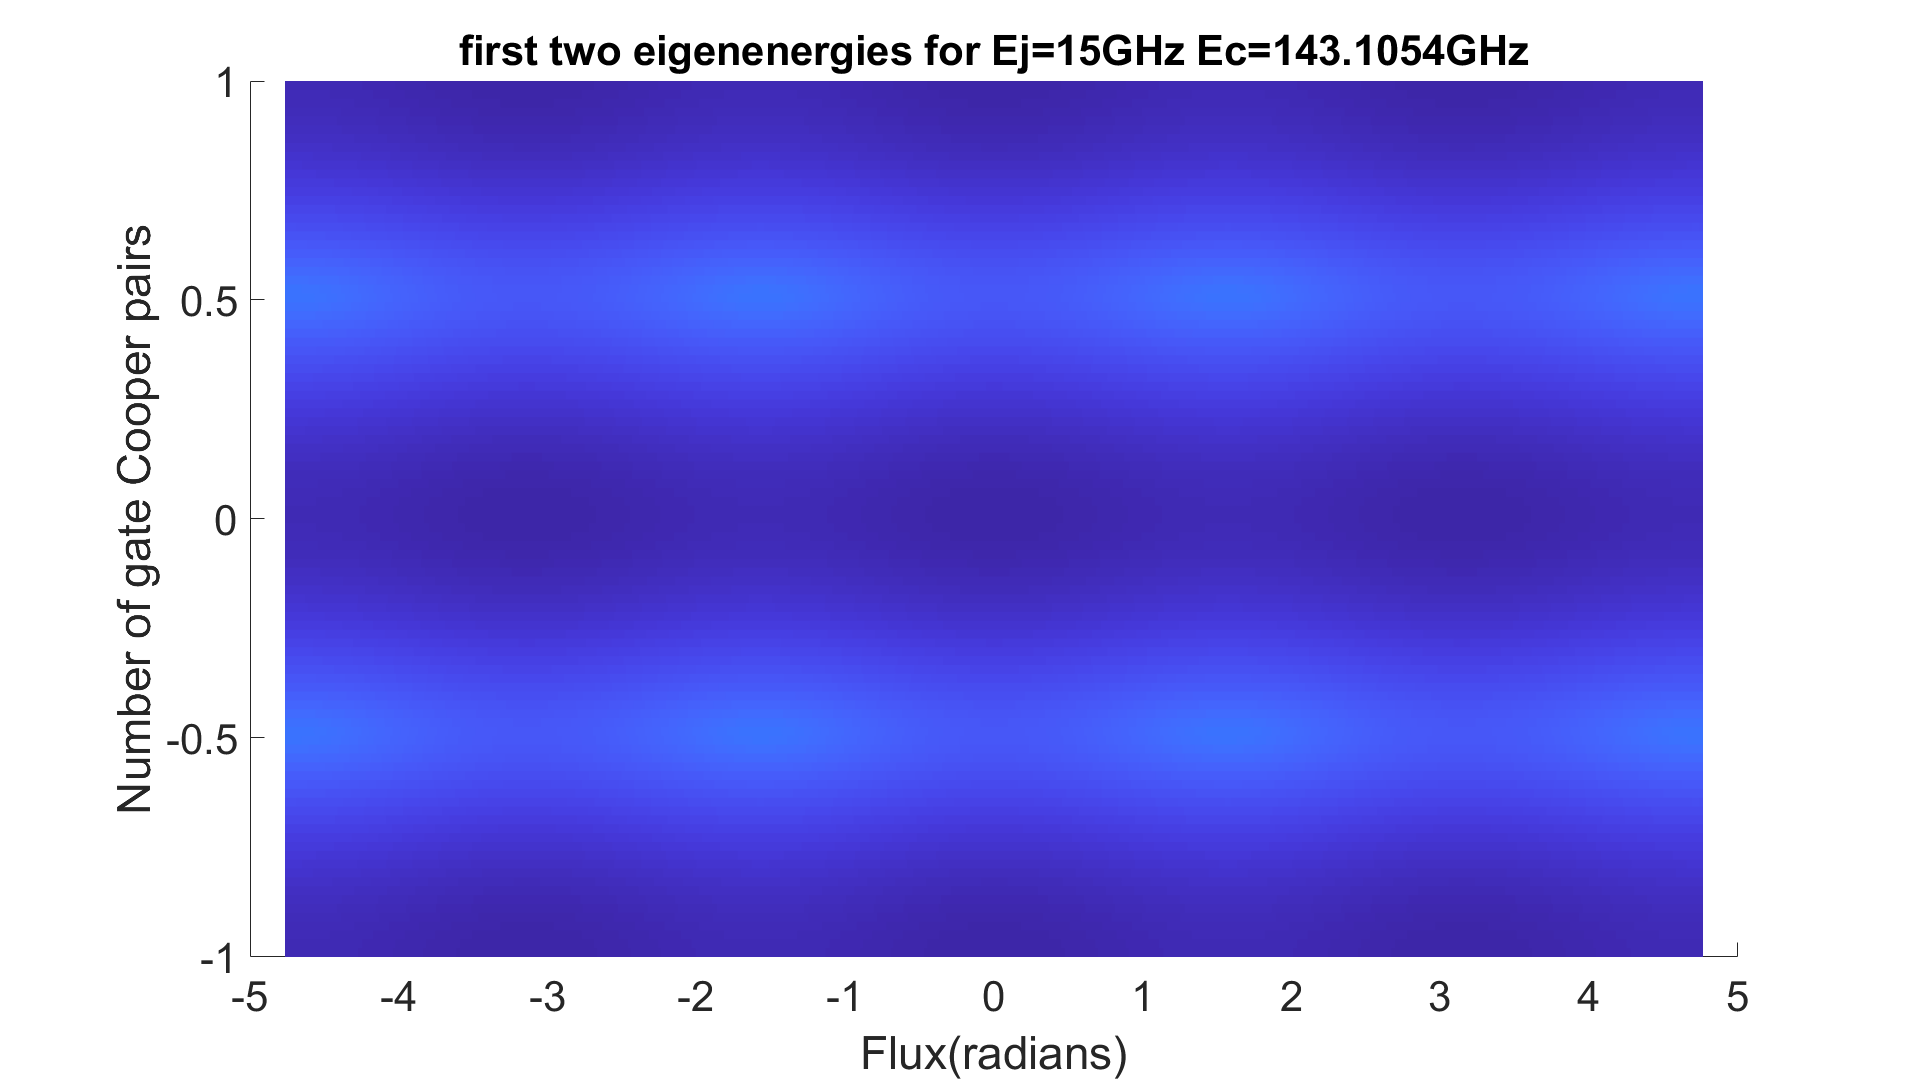


     %%%%%%%%%%%%%% plot eigenenergies if needed %%%%%%%%%%%%%%
    if plot_display==1
        figure
        hold on
         q=surf(gate_values_1,flux,E1);
        xlabel('Number of gate Cooper pairs');
        ylabel('Flux(radians)');
        zlabel('E (Hz)');
        set(q,'LineStyle','none');
        w=surf(gate_values_1,flux,E2);
        view(90,270);
        tit=['first two eigenenergies for Ej=' num2str(Ej/1e9) 'GHz Ec=' num2str(Ec/1e9) 'GHz'];
        title(tit);
        set(w,'LineStyle','none'); 
        hold off
        
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


    %%%%%%% initiate arrays for derivatives %%%%%%%%%%%%
    dE1=ones(size(E1));
    dE1squared=ones(size(E1));
    dE1cubed=ones(size(E1));
    dE1fourth=ones(size(E1));
    dE1x1squared=ones(size(E1x1));
    dE1x1fourth=ones(size(E1x1));
    dE1x3squared=ones(size(E1x3));
    dE1ng=ones(size(E1x1));
%     dE1ngsquared=ones(size(E1x1));
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    ngx0=CR1*(VR*Cj/e/Csigma*ones(1,length(gate_values_1))-gate_values_1/Csigma);

  %%%%%%%%%%%%%%  calculate 1st derivative wrt x for charging term %%%%%%%%%%%%%%%%%% 
    for i=1:length(flux)
        for j=1:length(gate_values_1)
            offset_number=number_points+1+(j-1)*(2*number_points+1);
            dE1ng_temp=numerical_derivative(E1ng(i,offset_number-number_points:offset_number+number_points),...
                gate(offset_number-number_points:offset_number+number_points),1);
            dE1ng(i,offset_number)=dE1ng_temp(number_points+1);
        end
    end 
    dE1ng=dE1ng(:,number_points+1:2*number_points+1:end);
    mean(mean(abs(dE1ng)))

ans = 7.0830e+10

    size(dE1ng)

ans =         2300         100


    size(ngx0)

ans =      1   100


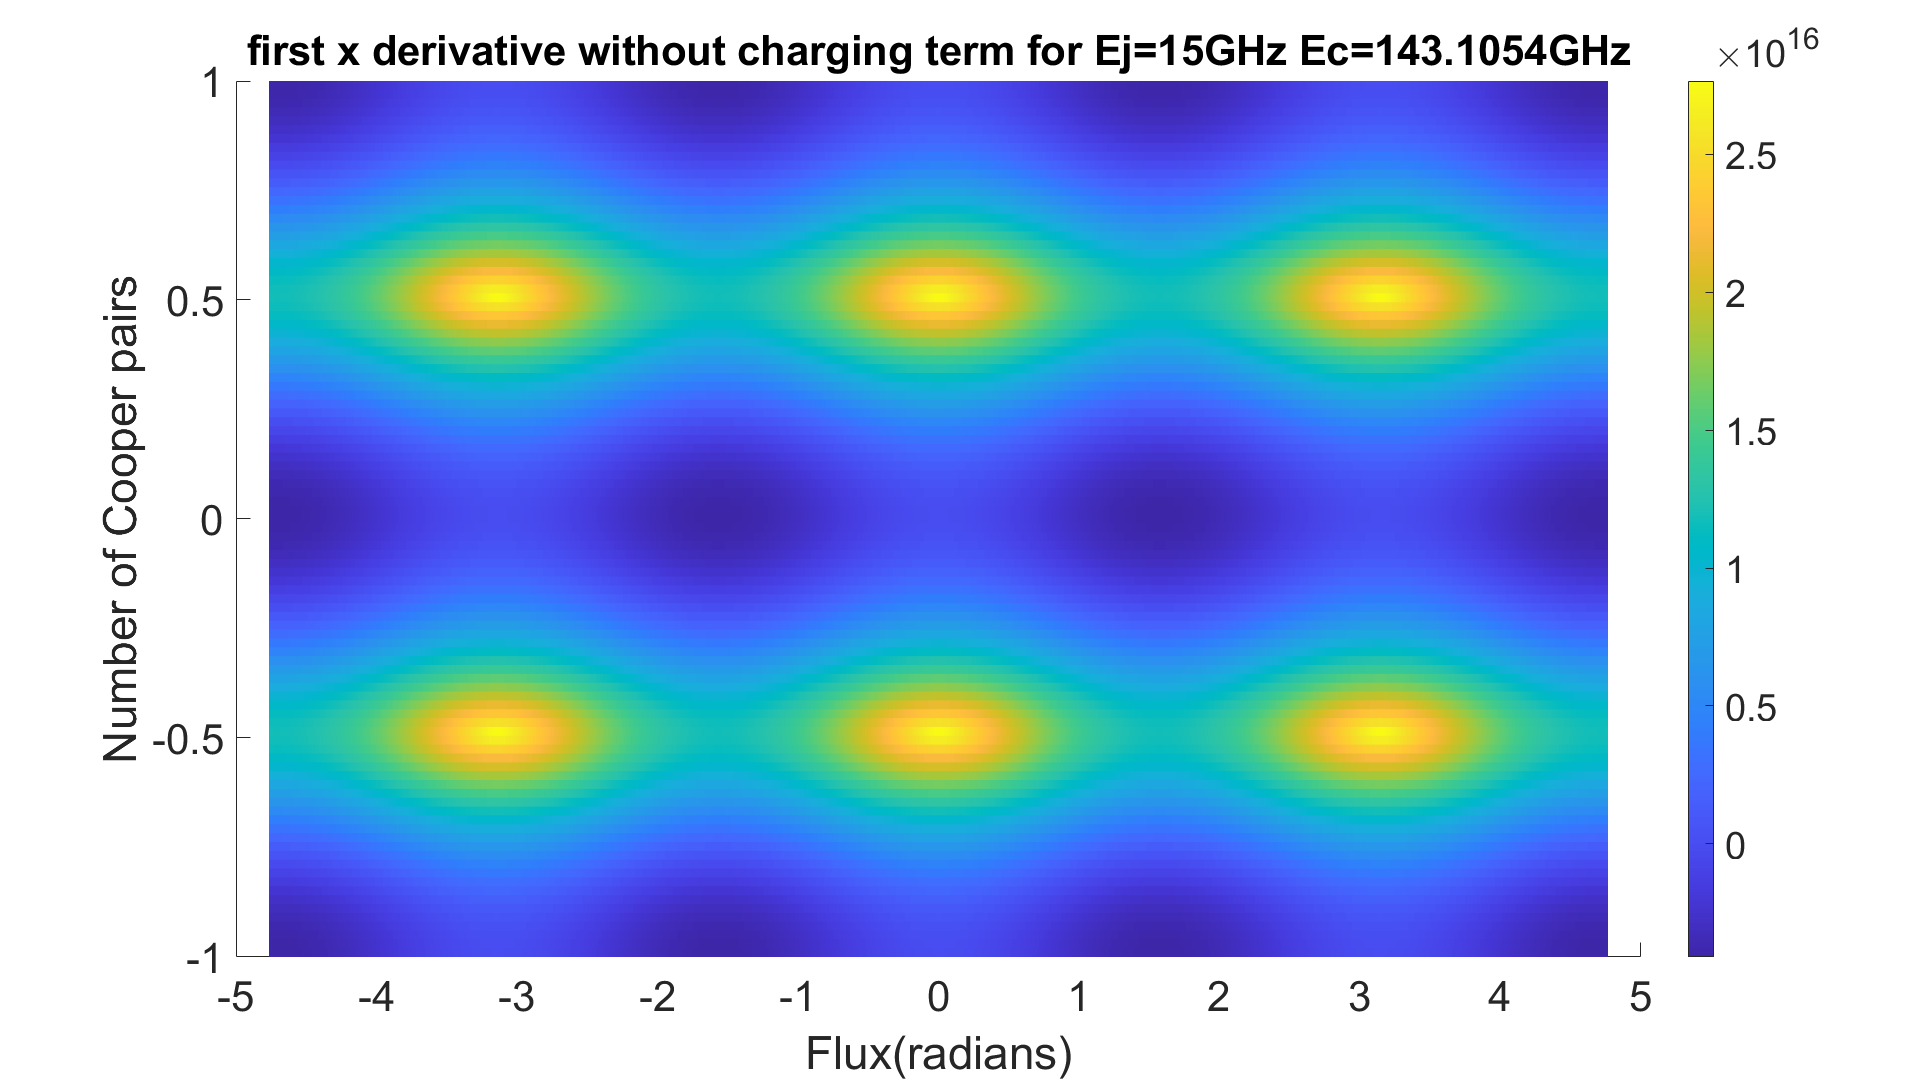

    for i=1:length(ngx0)
        dE1ng(:,i)=dE1ng(:,i)*ngx0(i);
    end
    if plot_display==1
        figure
        hold on
        q=surf(gate_values_1,flux,E1x1);
        xlabel('Number of Cooper pairs');
        ylabel('Flux(radians)');
        zlabel('first x derivative without charging term');
        set(q,'LineStyle','none')
        view(90,270);
        tit=['first x derivative without charging term for Ej=' num2str(Ej/1e9) 'GHz Ec=' num2str(Ec/1e9) 'GHz'];
        title(tit);
        hold off
        colorbar
    end

    E1x1=E1x1+dE1ng;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

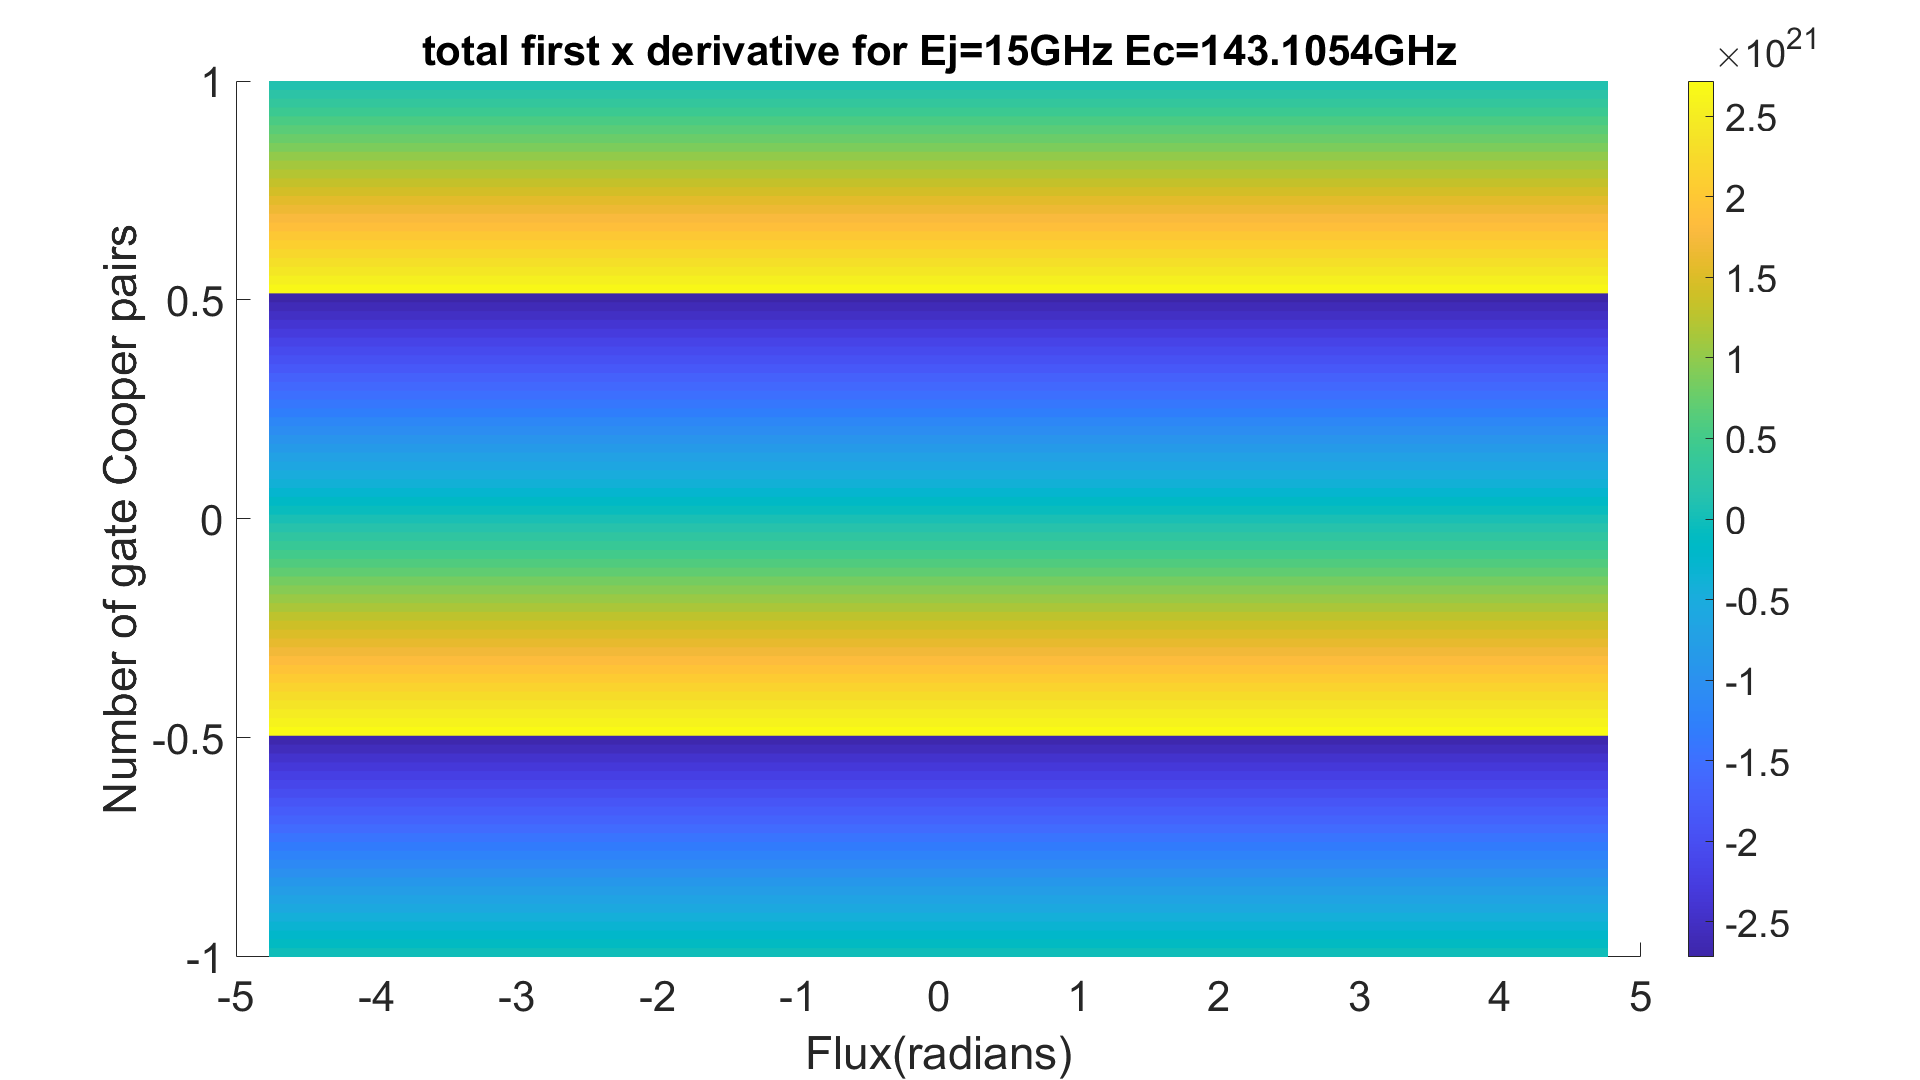

    %%%%%%%%%%%%%%%%%%%%%%%%% Plot 1st derivative wrt x for entire hamiltonian %%%%%%%%%%%%%%%%%%%%
    if plot_display==1
        figure
        hold on
         q=surf(gate_values_1,flux,E1x1);
        xlabel('Number of gate Cooper pairs');
        ylabel('Flux(radians)');
        zlabel('first x derivative of E (Hz)');
        set(q,'LineStyle','none');
        view(90,270);
        tit=['total first x derivative for Ej=' num2str(Ej/1e9) 'GHz Ec=' num2str(Ec/1e9) 'GHz'];
        title(tit);
        set(w,'LineStyle','none'); 
        hold off
        colorbar
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% size(E1)
%     size(dE1squared)
%     size(dE1cubed)
%     size(dE1fourth)
%     size(dE1ngsquared)
%     size(E1x1)
%     size(gate_values_1)

    %%%%%%%%%% calculate first 4 phi derivatives & freq shifts & couplings %%%%%%%%%%%%%%%%%%%%%%%%
%     E1=E1(:,number_points+1:2*number_points+1:end);
%     dE1squared=dE1squared(:,number_points+1:2*number_points+1:end);
%     dE1cubed=dE1cubed(:,number_points+1:2*number_points+1:end);
%     dE1fourth=dE1fourth(:,number_points+1:2*number_points+1:end);
%     dE1ngsquared=dE1ngsquared(:,number_points+1:2*number_points+1:end);

    
    for i=1:length(gate_values_1)
        for j=1:length(flux_values_1)
            dE1_temp=ones(2*number_points+1,1); 
            dE1squared_temp=ones(2*number_points+1,1);
            dE1cubed_temp=ones(2*number_points+1,1);
            dE1fourth_temp=ones(2*number_points+1,1);
            dE1x1squared_temp=ones(2*number_points+1,1);
            dE1x1fourth_temp=ones(2*number_points+1,1);
            dE1x3squared_temp=ones(2*number_points+1,1);
            offset_number=number_points+1+(j-1)*(2*number_points+1);
            dE1_temp(:)=numerical_derivative(E1(offset_number-number_points:offset_number+number_points,i),...
                flux(offset_number-number_points:offset_number+number_points),1);
            dE1(offset_number,i)=dE1_temp(number_points+1);
            dE1squared_temp(:)=numerical_derivative(E1(offset_number-number_points:offset_number+number_points,i),...
                flux(offset_number-number_points:offset_number+number_points),2);
            dE1squared(offset_number,i)=dE1squared_temp(number_points+1);
            dE1cubed_temp(:)=numerical_derivative(E1(offset_number-number_points:offset_number+number_points,i),...
                flux(offset_number-number_points:offset_number+number_points),3);
            dE1cubed(offset_number,i)=dE1cubed_temp(number_points+1);
            dE1fourth_temp(:)=numerical_derivative(E1(offset_number-number_points:offset_number+number_points,i),...
                flux(offset_number-number_points:offset_number+number_points),4);
            dE1fourth(offset_number,i)=dE1fourth_temp(number_points+1);
            dE1x1squared_temp(:)=numerical_derivative(E1x1(offset_number-number_points:offset_number+number_points,i),...
                flux(offset_number-number_points:offset_number+number_points),2);
            dE1x1squared(offset_number,i)=dE1x1squared_temp(number_points+1);
%             dE1x1squared_temp(:)=numerical_derivative(E1x1(offset_number-number_points:offset_number+number_points,i),...
%                 flux(offset_number-number_points:offset_number+number_points),2);
%             dE1x1squared(offset_number,i)=dE1x1squared_temp(number_points+1);
%             dE1x1fourth_temp(:)=numerical_derivative(E1x1(offset_number-number_points:offset_number+number_points,i),...
%                 flux(offset_number-number_points:offset_number+number_points),4);
%             dE1x1fourth(offset_number,i)=dE1x1fourth_temp(number_points+1);
%             dE1x3squared_temp(:)=numerical_derivative(E1x3(offset_number-number_points:offset_number+number_points,i),...
%                 flux(offset_number-number_points:offset_number+number_points),2);
%             dE1x3squared(offset_number,i)=dE1x3squared_temp(number_points+1);
        end
    end

    dE1=dE1(number_points+1:2*number_points+1:end,:);
    dE1squared=dE1squared(number_points+1:2*number_points+1:end,:);
    dE1cubed=dE1cubed(number_points+1:2*number_points+1:end,:);
    dE1fourth=dE1fourth(number_points+1:2*number_points+1:end,:);
    dE1x1squared=dE1x1squared(number_points+1:2*number_points+1:end,:);
%     dE1x1squared=dE1x1squared(number_points+1:2*number_points+1:end,number_points+1:2*number_points+1:end);
%     dE1x1fourth=dE1x1fourth(number_points+1:2*number_points+1:end,number_points+1:2*number_points+1:end);
%     dE1x3squared=dE1x3squared(number_points+1:2*number_points+1:end,number_points+1:2*number_points+1:end);
    freq_shift=1/4*dE1squared.*delta_0^2;%+1/2*dE1fourth.*delta_0^4;
    coupling=1/4*dE1x1squared*xzp*delta_0^2;%+1/24*delta_0^4*xzp*dE1x1fourth(12)+3/10*xzp^3*delta_0^28dE1x3squared;
%     freq_shift=freq_shift(b+1:end-a+1,d+1:end-c+1);
%     dE1=dE1(b+1:end-a+1,d+1:end-c+1);
%     dE1squared=dE1squared(b+1:end-a+1,d+1:end-c+1);
%     dE1cubed=dE1cubed(b+1:end-a+1,d+1:end-c+1);
%     dE1fourth=dE1fourth(b+1:end-a+1,d+1:end-c+1);
%     gate=gate(d+1:end-c+1)
%     flux=flux(b+1:end-a+1)
%     difference=diff(flux)
%     mean(difference)
%     flux_values_angle
%     diff(flux_values_angle)
%     gate_values_number
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% size(freq_shift)
% size(coupling)


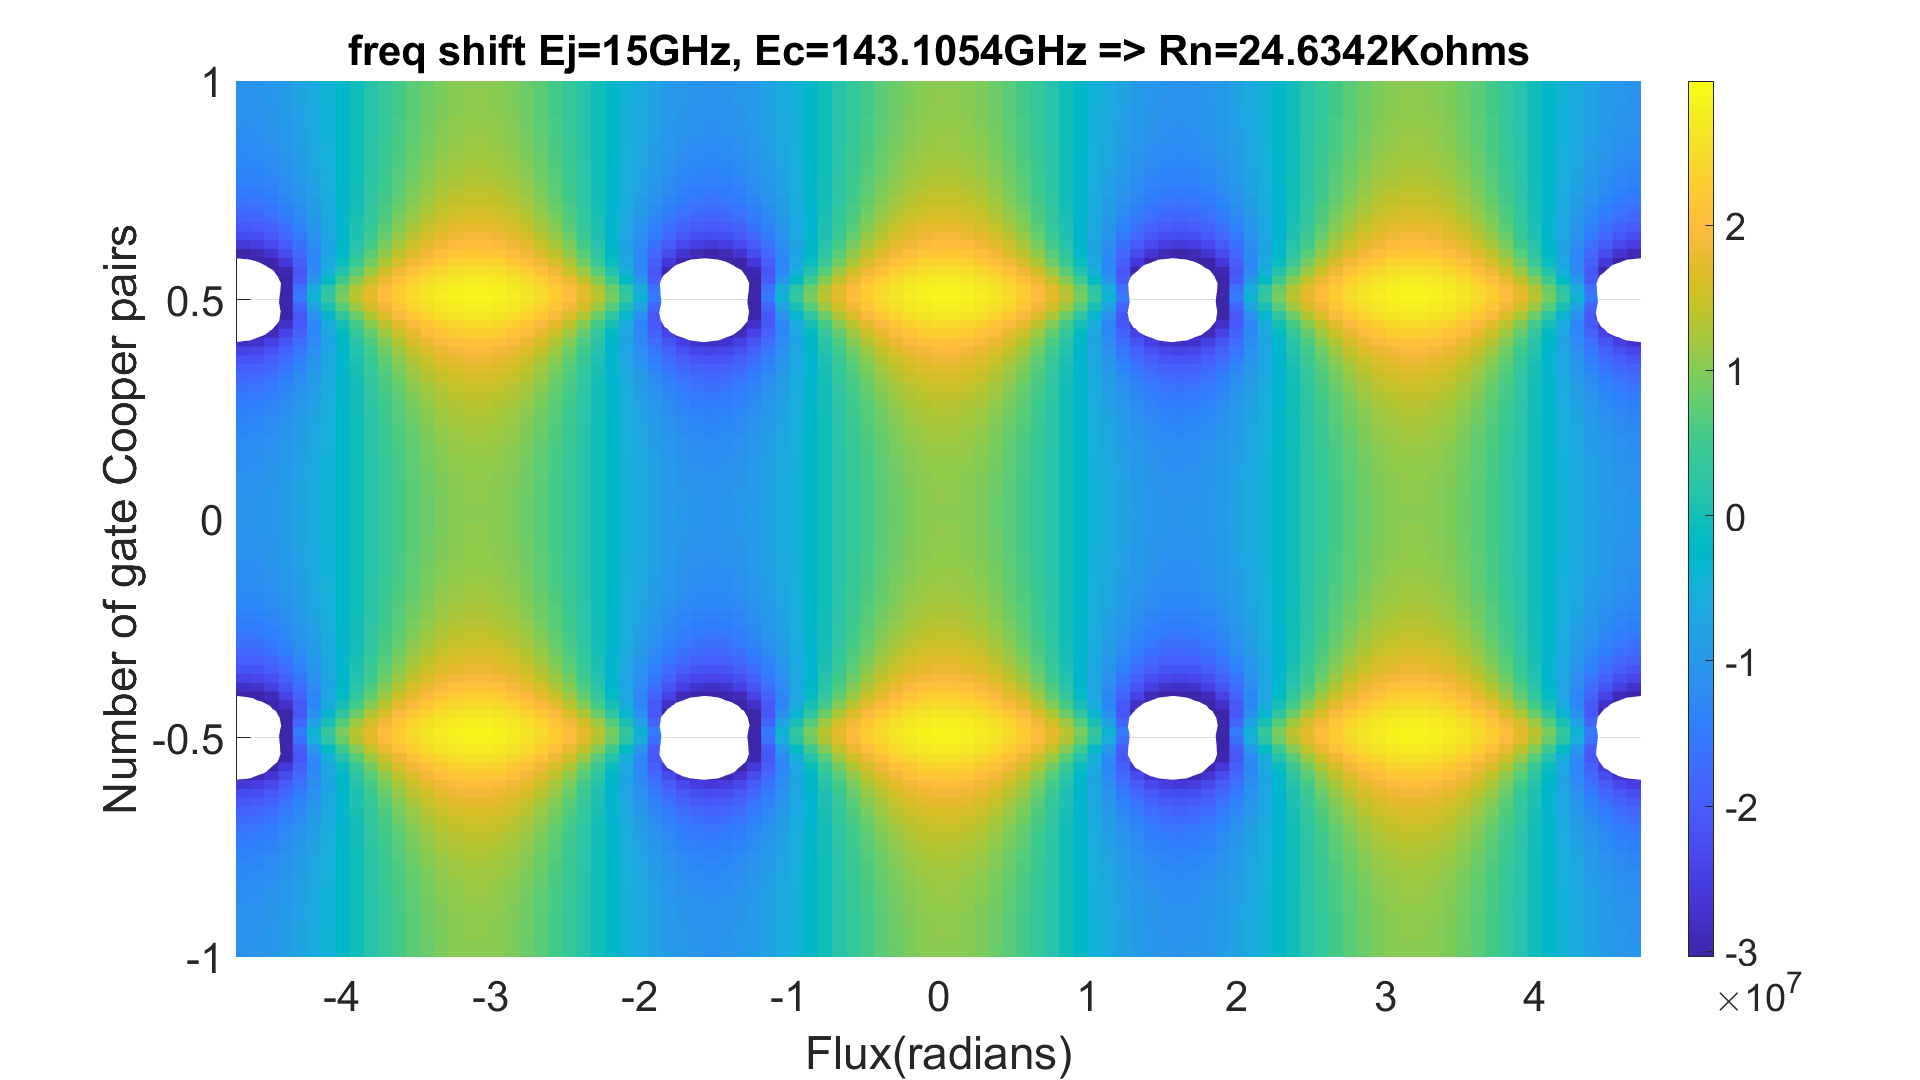

    
    
    freq_shift_reshaped=reshape(freq_shift,[length(flux_values_1)*length(gate_values_1),1]);
    figure
    r=surf(gate_values_1,flux_values_1,freq_shift);
    set(r,'LineStyle','none');
    view(90,270)
    xlabel('Number of gate Cooper pairs');
    ylabel('Flux(radians)');
    zlabel('freq shift');
    colorbar
    axis([gate_values_1(1) gate_values_1(end) flux_values_1(1) flux_values_1(end) mean(freq_shift_reshaped)-2*abs(std(freq_shift_reshaped)) mean(freq_shift_reshaped)+2*abs(std(freq_shift_reshaped))])
    caxis([mean(freq_shift_reshaped)-2*abs(std(freq_shift_reshaped))     mean(freq_shift_reshaped)+2*abs(std(freq_shift_reshaped))])
    h=6.626e-34;
    e=1.6e-19;
    Tc=1.2;
    Rn=1/4/pi/e/Ej*(Tc-.03)*635e-6;
    Rn=Rn/1e3;
    title(['freq shift Ej=' num2str(Ej/1e9) 'GHz, Ec=' num2str(Ec/1e9) 'GHz => Rn=' num2str(Rn) 'Kohms'])

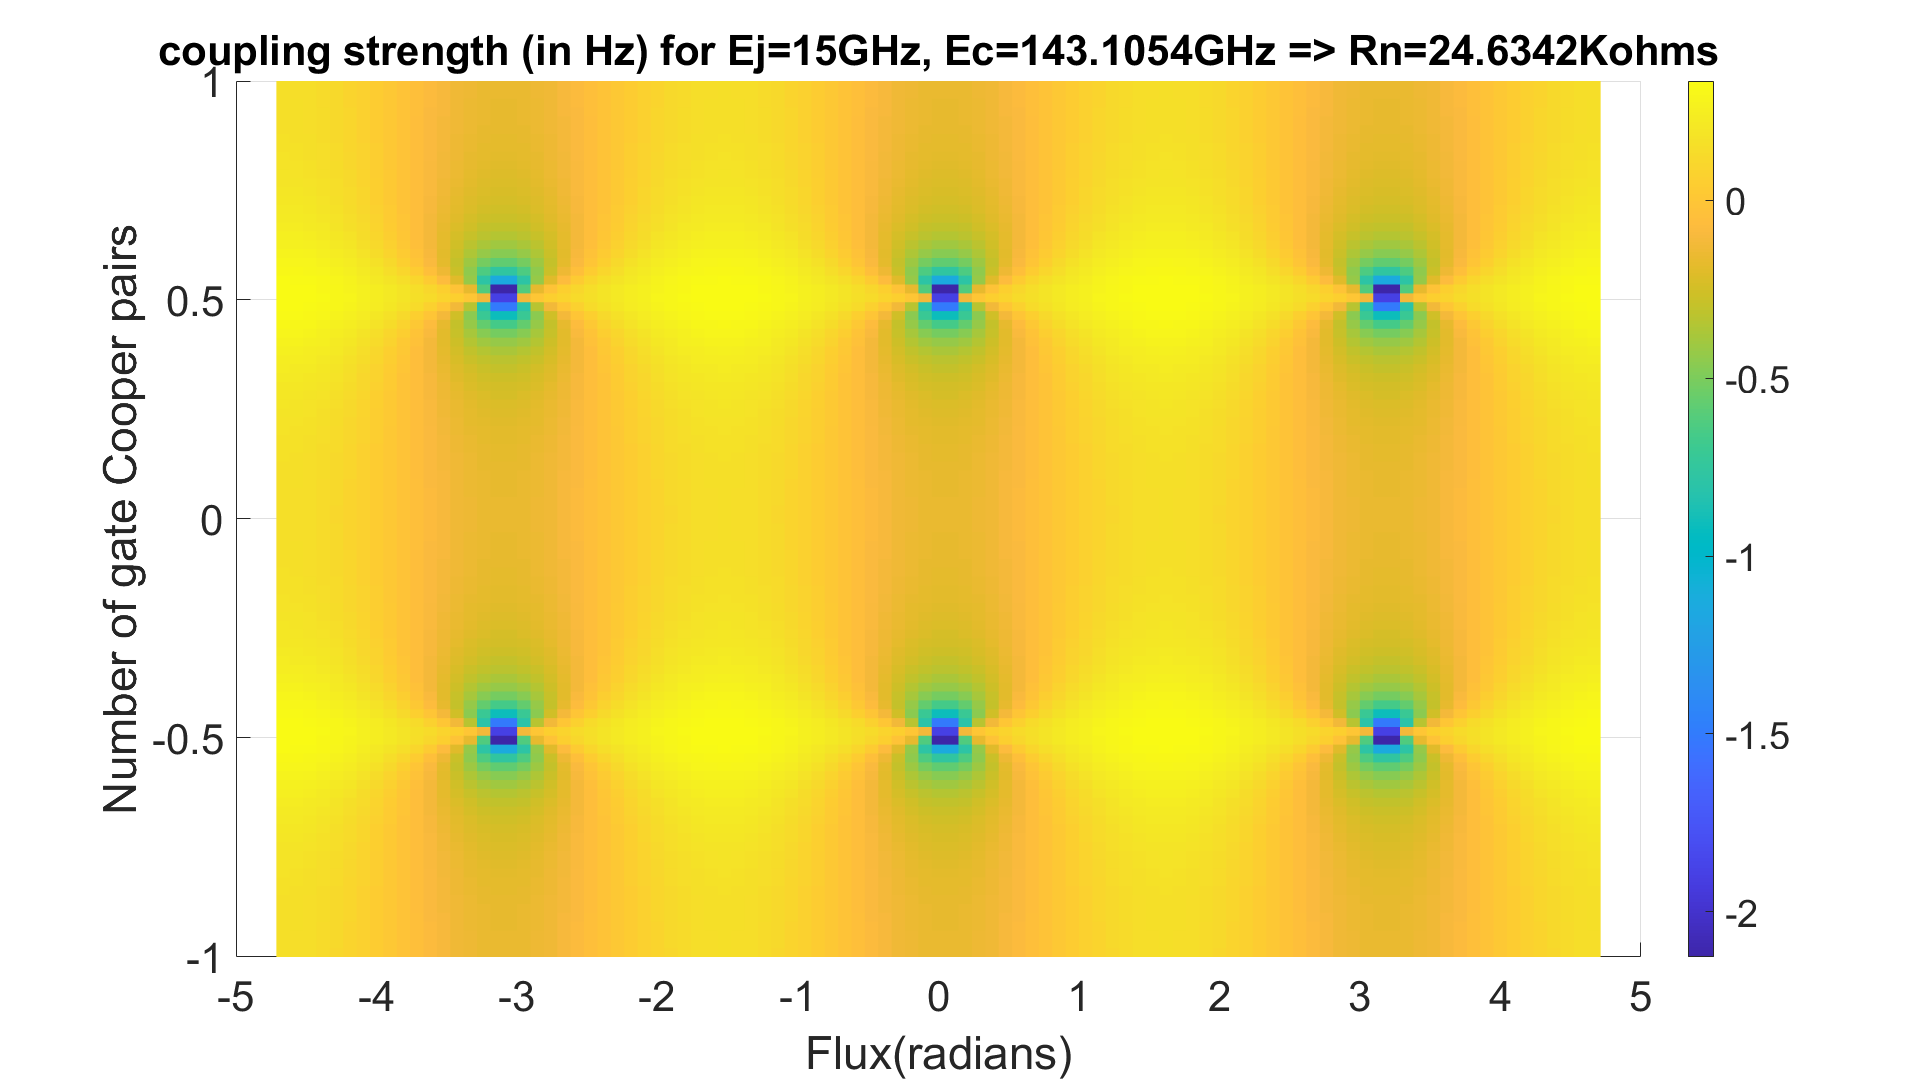

    
    figure
    r=surf(gate_values_1,flux_values_1,coupling);
    set(r,'LineStyle','none');
    view(90,270)
    xlabel('Number of gate Cooper pairs');
    ylabel('Flux(radians)');
    zlabel('coupling');
    colorbar
    title(['coupling strength (in Hz) for Ej=' num2str(Ej/1e9) 'GHz, Ec=' num2str(Ec/1e9) 'GHz => Rn=' num2str(Rn) 'Kohms']);

    % figure
%     r=surf(gate_values_1,flux_values_1,dE1);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate Cooper pairs');
%     ylabel('Flux(radians)');
%     zlabel('dE1');
%     colorbar
%     title('dE1')
%     
%     figure
%     r=surf(gate_values_1,flux_values_1,dE1squared);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate Cooper pairs');
%     ylabel('Flux(radians)');
%     zlabel('dE1dquared');
%     colorbar
%     title('dE1squared')
%     
%     figure
%     r=surf(gate_values_1,flux_values_1,dE1cubed);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate Cooper pairs');
%     ylabel('Flux(radians)');
%     zlabel('dE1cubed');
%     colorbar
%     title('dE1cubed')
%     
%     figure
%     r=surf(gate_values_1,flux_values_1,dE1fourth);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate Cooper pairs');
%     ylabel('Flux(radians)');
%     zlabel('dE1fourth');
%     colorbar
%     title('dE1fourth')
    %     for i=1:3
%         t=randi(length(gate_values_1));
%         figure
%         hold on
%         plot(flux_values_1,dE1x1squared(:,t)/(max(max(dE1x1squared))-min(min(dE1x1squared))))
%         plot(flux,E1x1(:,t)/(max(max(E1x1))-min(min(E1x1))),'x')
%         hold off
%         title(['ng=' num2str(gate_values_1(t))])
%         hold off
%     end
%     for i=1:3
%         t=randi(length(flux_values_1));
%         figure
%         hold on
%         plot(gate_values_1,dE1x1squared(t,:)/(max(max(dE1x1squared))-min(min(dE1x1squared))))
%         plot(gate,E1x1(t,:)/(max(max(E1x1))-min(min(E1x1))),'x')
%         hold off
%     end
%     
    

    %%%%%%%%%%%%%%%%
    %troubleshooting
    % E1(1,1)
    % E2(1,1)   
    % eigenvalue(1,1,1)
    % eigenvalue(2,1,1)
%     H(:,:,1,1)
    % eig(H(:,:,1,1))
    % (1-gate(1)/2)^2
    % (2-gate(1)/2)^2
    % (3-gate(1)/2)^2
    % (4-gate(1)/2)^2
    % (5-gate(1)/2)^2
    % -Ej*cos(flux(1))
    %%%%%%%%%%%%%%%%%%%%